% Read the Excel file into a table
T = readtable('transp1.xlsx');

**Graficas comercio maritimo**

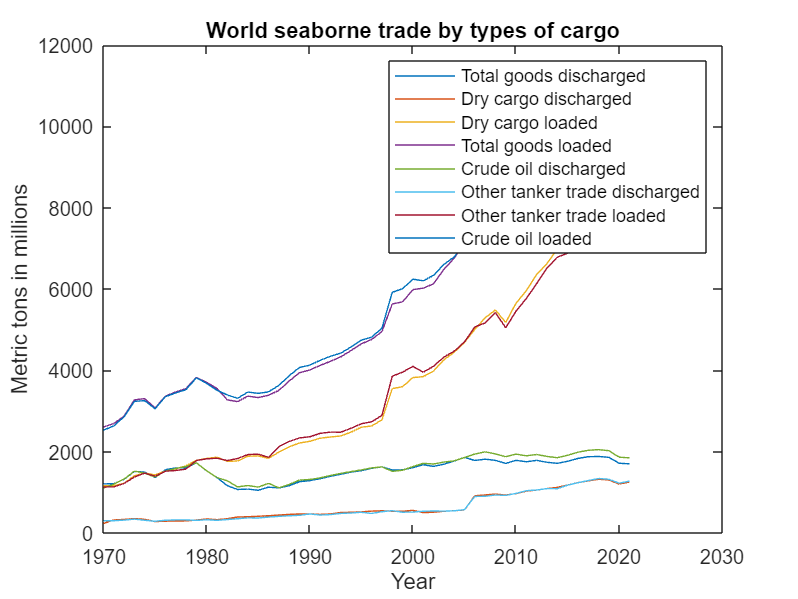


Comercio_maritimo_mundial_por_tipos_de_carga = table2array(T(1:8,3:end));
t=1970:2021;

plot(t,Comercio_maritimo_mundial_por_tipos_de_carga')

legend('Total goods discharged','Dry cargo discharged','Dry cargo loaded','Total goods loaded','Crude oil discharged','Other tanker trade discharged','Other tanker trade loaded','Crude oil loaded')
title("World seaborne trade by types of cargo")
xlabel("Year")
ylabel("Metric tons in millions")

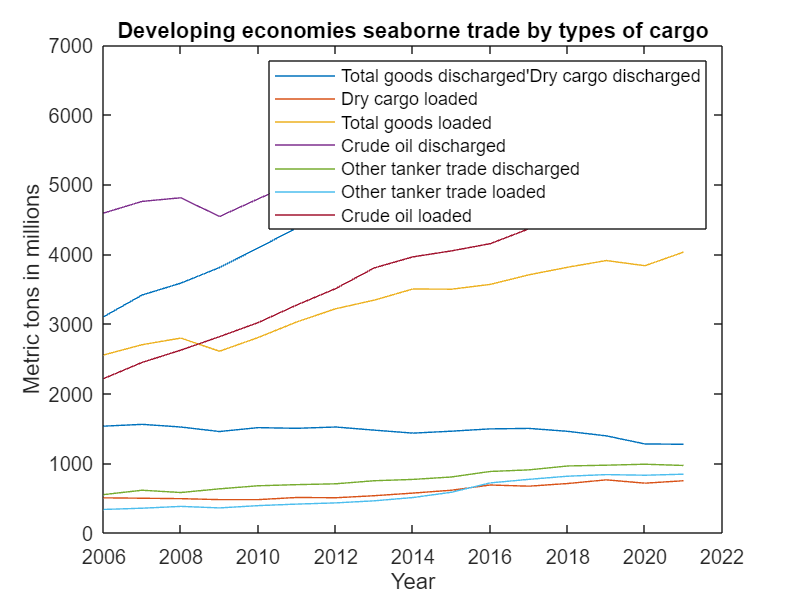

Comercio_maritimo_ecdesarrollandose = table2array(T(73:80,39:end));
t1=2006:2021;
plot(t1,Comercio_maritimo_ecdesarrollandose')

legend('Total goods discharged''Dry cargo discharged','Dry cargo loaded','Total goods loaded','Crude oil discharged','Other tanker trade discharged','Other tanker trade loaded','Crude oil loaded')
title("Developing economies seaborne trade by types of cargo")
xlabel("Year")
ylabel("Metric tons in millions")

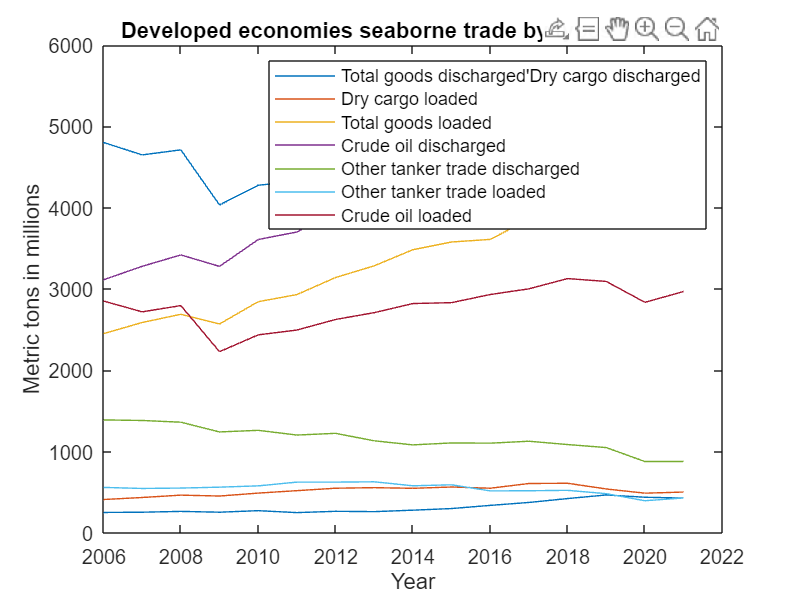

Comercio_maritimo_ecdesarrollandas = table2array(T(121:128,39:end));
t1=2006:2021;
plot(t1,Comercio_maritimo_ecdesarrollandas')

legend('Total goods discharged''Dry cargo discharged','Dry cargo loaded','Total goods loaded','Crude oil discharged','Other tanker trade discharged','Other tanker trade loaded','Crude oil loaded')
title("Developed economies seaborne trade by types of cargo")
xlabel("Year")
ylabel("Metric tons in millions")

**Grafica Indice de conectividad de paises**

clf
bar(U)
% Personalizar el gráfico
xlabel('Countries')
ylabel('Values')
title('Liner shipping connectivity index, Q1 2024')
vector = [4, 9, 14, 19, 26, 29, 34, 45, 50, 59, 64, 68, 79, 84, 87, 91, 99, 105, 110, 115, 128,132, 149, 155, 163, 169, 175, 179];
Paises(115)="Netherlands"

Paises = 181×1 string array
    "Albania"
    "Algeria"
    "American Samoa"
    "Angola"
    "Anguilla"
    "Antigua and Barbuda"
    "Argentina"
    "Aruba"
    "Australia"
    "Bahamas"
    "Bahrain"
    "Bangladesh"
    "Barbados"
    "Belgium"
    "Belize"
    "Benin"
    "Bermuda"
    "Bonaire, Sint Eustatius and Saba"
    "Brazil"
    "British Virgin Islands"
    "Brunei Darussalam"
    "Bulgaria"
    "Cabo Verde"
    "Cambodia"
    "Cameroon"
    "Canada"
    "Cayman Islands"
    "Chile"
    "China"
    "China, Hong Kong SAR"


Paises(175)="USA"

Paises = 181×1 string array
    "Albania"
    "Algeria"
    "American Samoa"
    "Angola"
    "Anguilla"
    "Antigua and Barbuda"
    "Argentina"
    "Aruba"
    "Australia"
    "Bahamas"
    "Bahrain"
    "Bangladesh"
    "Barbados"
    "Belgium"
    "Belize"
    "Benin"
    "Bermuda"
    "Bonaire, Sint Eustatius and Saba"
    "Brazil"
    "British Virgin Islands"
    "Brunei Darussalam"
    "Bulgaria"
    "Cabo Verde"
    "Cambodia"
    "Cameroon"
    "Canada"
    "Cayman Islands"
    "Chile"
    "China"
    "China, Hong Kong SAR"


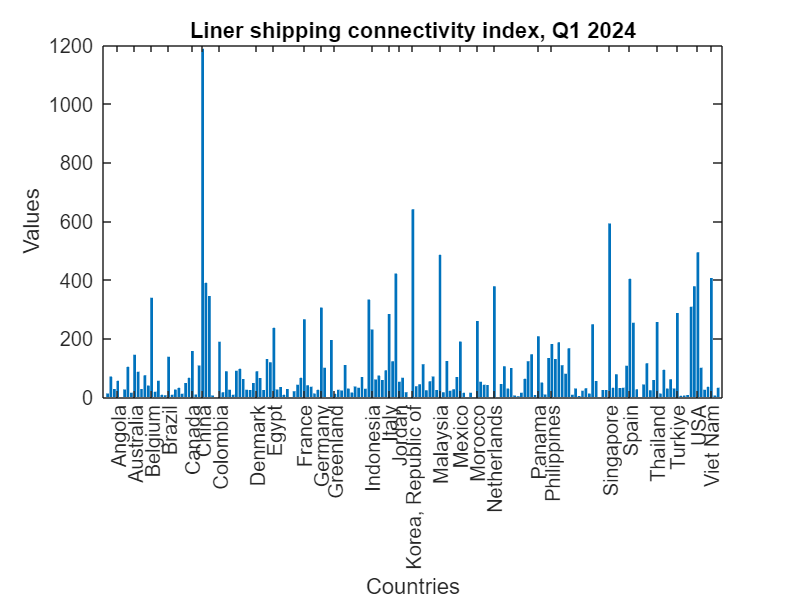

xticks(vector)
xtickangle(90)
xticklabels(Paises(vector)) % Etiquetas de las categorías en el eje x

[valores_ordenados, indices_ordenados] = sort(U, 'descend');
valores_ordenados(12:end)

ans =   344.5600
  338.9100
  332.2100
  307.9000
  305.0600
  286.9400
  282.9900
  264.9000
  259.3300
  255.7500


indices_ordenados(12:end)

ans =     31
    14
    78
   173
    64
   169
    84
    59
   110
   163


%España es 8o pais con mejor conectividad

**Grafica Major puertos de españa**


Pesp=Q12024_Index_Average_Q1_2023__100_Value2;
Pesp

Pesp =   535.3200
   46.9400
   10.5200
   51.9900
   10.1700
  498.8400
  104.7200
   48.6400
   18.7700
   71.8600



%pie(Pesp)
% Coordinates of the ports in Spain
lat = [36.1296, 38.3467, 36.8365, 28.9637, 43.5541, 41.3851, 43.2627, 36.5271, 37.6058, 39.9756, 35.8884, 43.4824, 38.9675, 43.5407, 37.2614, 43.3623, 28.1236, 36.7202, 42.2168, 35.0014, 37.1921, 39.5696, 43.3193, 28.6052, 39.523, 28.0943, 28.6835, 28.4682, 43.4623, 37.3886, 41.1114, 39.9334, 27.8095, 42.2389, 42.2643];
lon = [-5.4416, -0.4829, -2.4611, -13.5377, -6.0224, 2.1734, -2.9376, -6.2886, -0.9862, -0.0616, -5.3176, -8.2319, -0.1781, -5.6615, -6.9498, -8.4115, -15.435, -4.4179, -8.703, -3.5797, -3.5179, -3.3935, -8.5253, -17.0773, -0.2566, -17.1134, -17.7647, -16.2485, -4.2207, -5.9845, 1.249, -0.164, -17.9147, -8.7207, -8.7226];
tamanos = (Pesp/sum(Pesp))*550; % Defining a size of 10 for the port markers
tamanos

tamanos =   106.4366
    9.3330
    2.0917
   10.3371
    2.0221
   99.1834
   20.8213
    9.6710
    3.7320
   14.2878


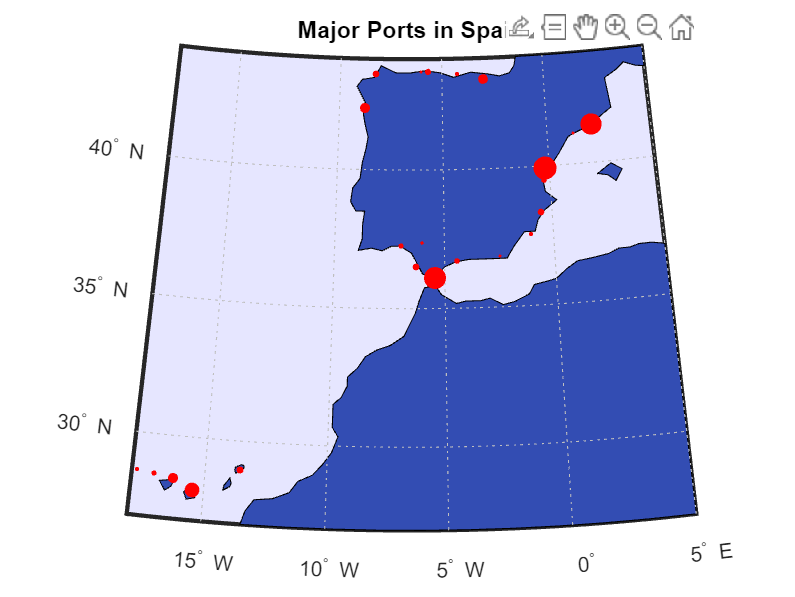


% Definir las coordenadas de España 
latlim = [27 44]; % Latitud desde el extremo sur de las Islas Canarias hasta el extremo norte de la Península Ibérica
lonlim = [-18 5]; % Longitud desde el extremo oeste de las Islas Canarias hasta el extremo este de la Península Ibérica
load coastlines
% Crear el gráfico geográfico limitado a España, incluyendo las Islas Canarias
figure;
ax = worldmap(latlim, lonlim);

% Establecer colores de fondo para el mar y la tierra
landColor = [0.2 0.3 0.7]; % Color para la tierra 
seaColor = [0.9 0.9 1]; % Color para el mar (azul claro)

% Mostrar el mapa con colores de fondo diferenciados para tierra y mar
setm(ax, 'FFaceColor', seaColor); % Establecer color de fondo para el mar
geoshow(ax, coastlat, coastlon, 'DisplayType', 'polygon', 'FaceColor', landColor); % Mostrar la tierra
scatterm(lat, lon, tamanos+0.01,'red ','filled');


% % Adding a title and labels
 title('Major Ports in Spain');
 xlabel('Longitude');
 ylabel('Latitude');

**Grafica crecimiento puertos de España**

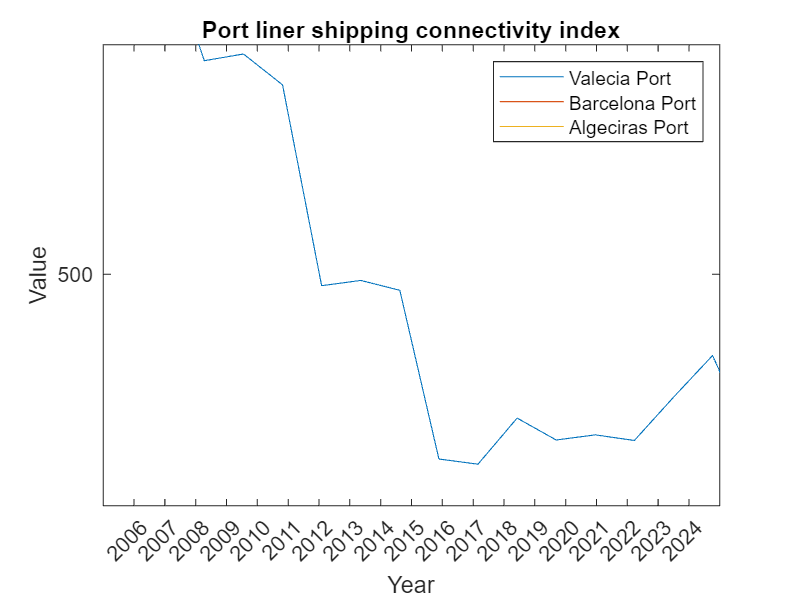

clf
%Pvlc=p1
%Pbarc=p1
%Palg=p1
t=2006:0.25:2024;

years=2006:2024;
% Crear el gráfico
figure;
plot(t, [Pvlc;Pbarc;Palg]');
xlabel('Year');
ylabel('Value');
legend('Valecia Port', 'Barcelona Port', 'Algeciras Port');
title('Port liner shipping connectivity index')
% Establecer los marcadores del eje x para mostrar solo un año por cada año real
xticks(2006:1:2024);